# **Script illustrating the relationship between cone spacing and point spread function in the default cone mosaic and optics models for the treeshrew and the human visual system**

*This script illustrates the relationship between cone spacing and the PSF in the human model*

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2018*

# **Step 1.** Generate default human optics and cone mosaics

% Generate default human optics 
defaultHumanOI = oiCreate('wvf human');

% Generate a 0.1 deg human cone mosaic with default params
defaultHumanConeMosaic = coneMosaicHex(7, ...
    'eccBasedConeDensity', true, ...
    'maxGridAdjustmentIterations',200, ...
    'fovDegs', [0.1 0.1]);


Hex grid adjustment: on iteration 1 ...
Hex grid adjustment: on iteration 51 ...
Hex grid adjustment: on iteration 101 ...
Hex grid adjustment: on iteration 151 ...
Hex grid adjustment: on iteration 201 ...
Hex grid smoothing finished in 14.8 seconds.
Did not converge, but exceeded max number of iterations (200).
Max(movement) in last iteration: 0.036867, Tolerange: 0.001000

Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 20
Scones after making an S-cone free central patch: 0 (added Lcones:13, added Mcones:7)


# Step 2. Co-visualize cone mosaics and PSFs at 3 wavelengths

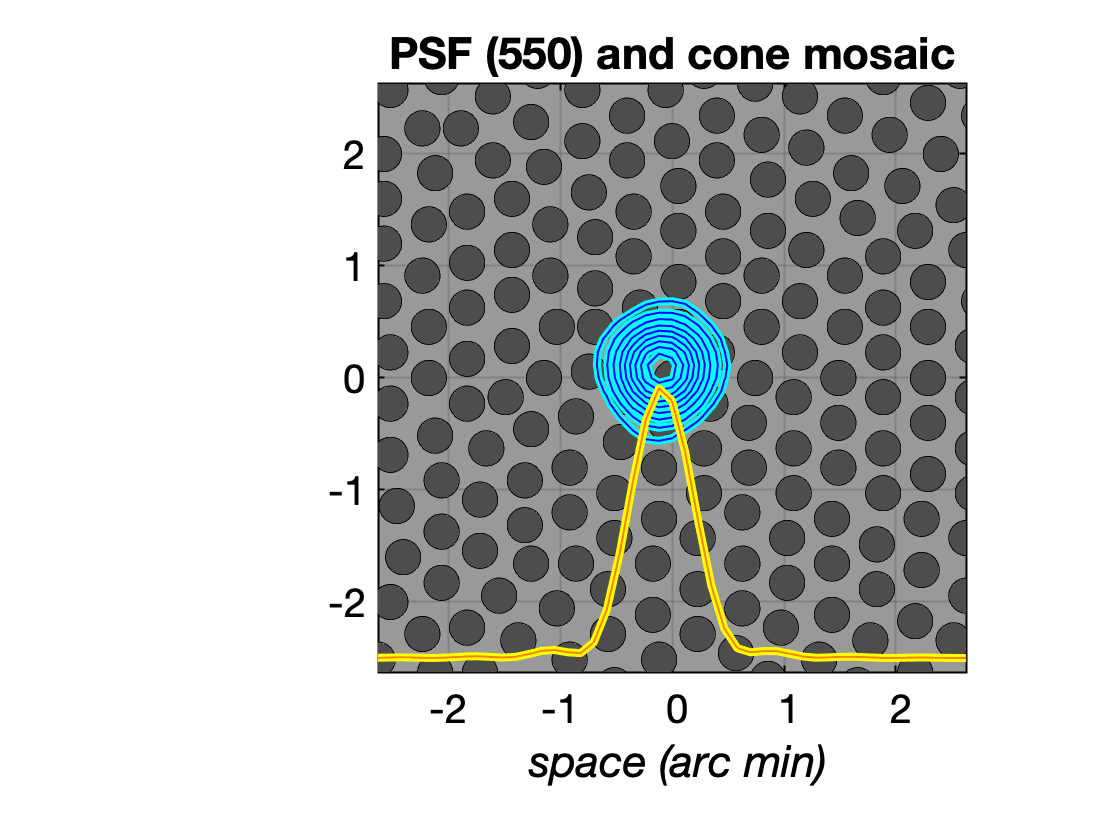

% Co-visualize the human PSF (in-focus wavelength) and cone mosaic
visualizedSpatialSupportArcMin = 5;
visualizedWavelength = 550;
visualizePSF(defaultHumanOI, visualizedWavelength, ...
    visualizedSpatialSupportArcMin, ...
    'withSuperimposedMosaic', defaultHumanConeMosaic, ...
    'figureTitle', sprintf('PSF (%d) and cone mosaic', visualizedWavelength));

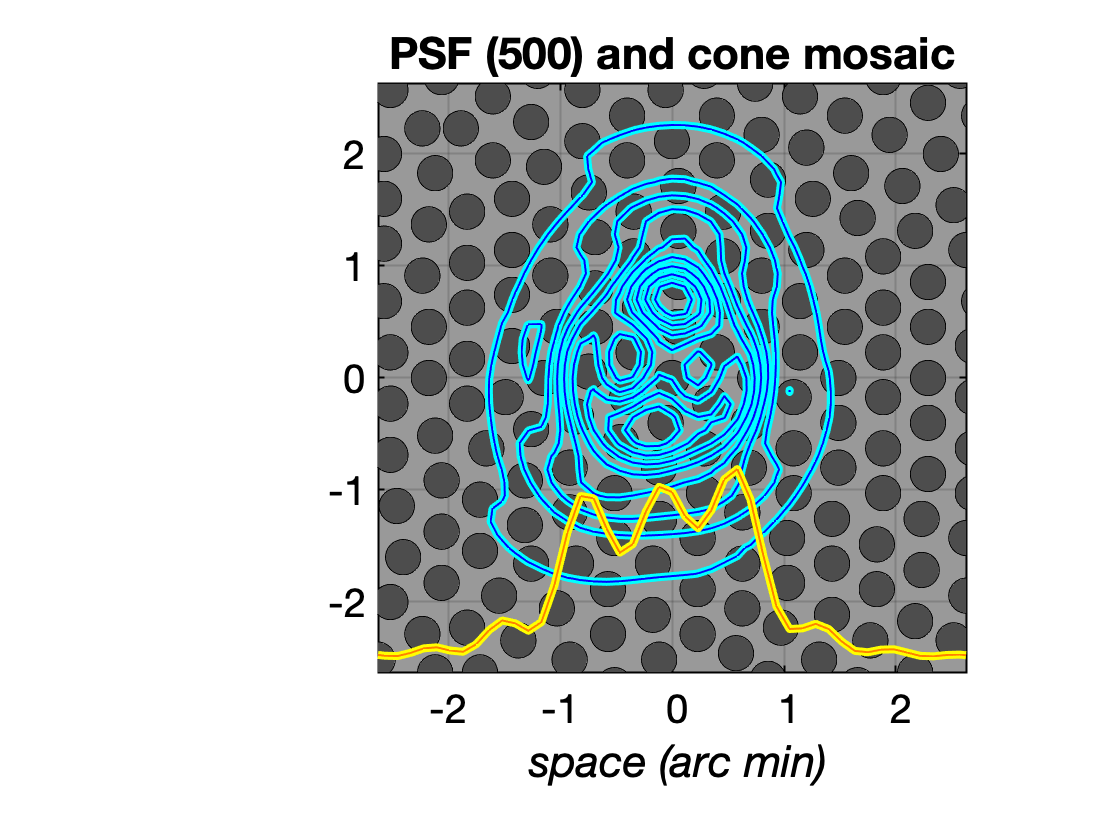


visualizedWavelength = 500;
visualizePSF(defaultHumanOI, visualizedWavelength, ...
    visualizedSpatialSupportArcMin, ...
    'withSuperimposedMosaic', defaultHumanConeMosaic, ...
    'figureTitle', sprintf('PSF (%d) and cone mosaic', visualizedWavelength));

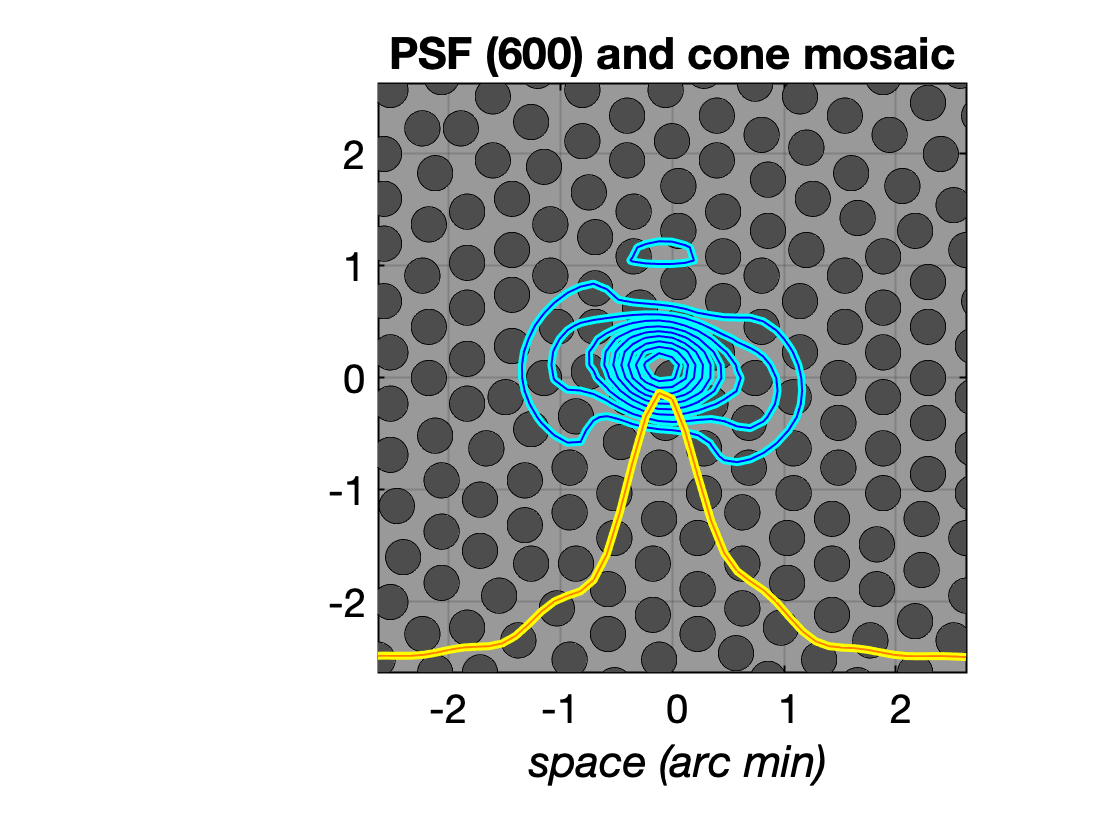


visualizedWavelength = 600;
visualizePSF(defaultHumanOI, visualizedWavelength, ...
    visualizedSpatialSupportArcMin, ...
    'withSuperimposedMosaic', defaultHumanConeMosaic, ...
    'figureTitle', sprintf('PSF (%d) and cone mosaic', visualizedWavelength));